clc; clearvars; close all;

syms x_0 y_0 real
syms v(t) theta_m(t) omega(t)
x = x_0 + int(v * cos(theta_m), 0, t)

$$x = x_{0}+\int_{0}^{t}\cos\left(\theta_{m}\left(t\right)\right)\,v\left(t\right)\mathrm{d}t$$

y = y_0 + int(v * sin(theta_m), 0, t)

$$y = y_{0}+\int_{0}^{t}\sin\left(\theta_{m}\left(t\right)\right)\,v\left(t\right)\mathrm{d}t$$

syms v_0 omega_0 theta_0 taw real
theta_m_ = theta_0 + int(omega_0, taw, 0, t)

$$theta\_m\_ = \theta_{0}+\omega_{0}\,t$$

x = subs(x, [v, theta_m], [v_0, theta_m_])

$$x = x_{0}+\frac{v_{0}\,\left(\sin\left(\theta_{0}+\omega_{0}\,t\right)-\sin\left(\theta_{0}\right)\right)}{\omega_{0}}$$

limit(x, omega_0, 0)

$$ans = x_{0}+t\,v_{0}\,\cos\left(\theta_{0}\right)$$

y = subs(y, [v, theta_m], [v_0, theta_m_])

$$y = y_{0}-\frac{v_{0}\,\left(\cos\left(\theta_{0}+\omega_{0}\,t\right)-\cos\left(\theta_{0}\right)\right)}{\omega_{0}}$$

limit(y, omega_0, 0)

$$ans = y_{0}+t\,v_{0}\,\sin\left(\theta_{0}\right)$$

x = subs(x, [x_0, theta_0, omega_0, v_0], [0, 0, 1, 2])

$$x = 2\,\sin\left(t\right)$$

y = subs(y, [y_0, theta_0, omega_0, v_0], [0, 0, 1, 2])

$$y = 2-2\,\cos\left(t\right)$$

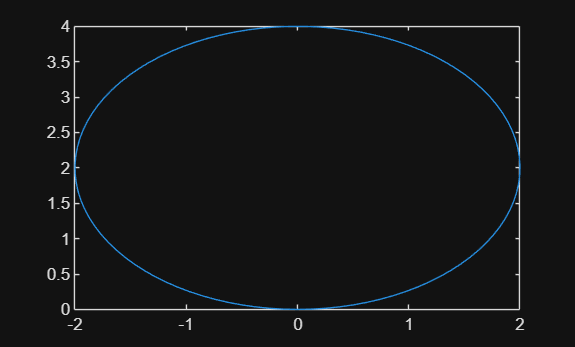

x_t = matlabFunction(x, 'Vars',t);
y_t = matlabFunction(y, 'Vars',t);
t = linspace(0, 2*pi, 100);
plot(x_t(t), y_t(t));

% simplify(simplify(expand(x^2)) + simplify(expand(y^2)))